# TB2kp TB test for TBG

## 生成TBG TB

addpath('..');
TBG = HR(28);
TBG = TBG <'POSCAR';
TBG = TBG <'KPOINTS';
TBG.orbL

ans =     0.8096    0.0476    0.4272
    0.9524    0.7619    0.4272
    0.2381    0.1904    0.4272
    0.1904    0.9524    0.4272
    0.0476    0.2381    0.4272
    0.7619    0.8096    0.4272
    0.0476    0.8096    0.5728
    0.7619    0.9524    0.5728
    0.1904    0.2381    0.5728
    0.9524    0.1904    0.5728


TBG.quantumL

ans =      2     1     0     1
     2     1     0     1
     2     1     0     1
     3     1     0     1
     3     1     0     1
     3     1     0     1
     2     1     0     1
     2     1     0     1
     2     1     0     1
     3     1     0     1


- 进行 nn_sk 搜索

- 这里 search_range 取 【1 1 0】，Accuracy 取小数点3位，maxR值取 5 埃

search_range = [1 1 0];
Accuracy = 3;
r_max_search = 3.8;
d_max = 3.8       ;
TBG = TBG.nn_sk_smart(search_range,Accuracy ,r_max_search);

The (   1/  28) th orb nn information has been generated.
The (   2/  28) th orb nn information has been generated.
The (   3/  28) th orb nn information has been generated.
The (   4/  28) th orb nn information has been generated.
The (   5/  28) th orb nn information has been generated.
The (   6/  28) th orb nn information has been generated.
The (   7/  28) th orb nn information has been generated.
The (   8/  28) th orb nn information has been generated.
The (   9/  28) th orb nn information has been generated.
The (  10/  28) th orb nn information has been generated.
The (  11/  28) th orb nn information has been generated.
The (  12/  28) th orb nn information has been generated.
The (  13/  28) th orb nn information has been generated.
The (  14/  28) th orb nn information has been generated.
The (  15/  28) th orb nn information has been generated.
The (  16/  28) th orb nn information has been generated.
The (  17/  28) th orb nn information has been generated.
The (  18/  28

- 可以简要获取一下这一步的信息，看下Rnn排名

[Rnn,~,~,~] = HR.nn_information(TBG)

the   1 th Rnn vector:  1.4250 Angstrom
the   2 th Rnn vector:  2.4680 Angstrom
the   3 th Rnn vector:  2.4690 Angstrom
the   4 th Rnn vector:  2.8500 Angstrom
the   5 th Rnn vector:  3.3500 Angstrom
the   6 th Rnn vector:  3.3930 Angstrom
the   7 th Rnn vector:  3.4780 Angstrom
the   8 th Rnn vector:  3.5190 Angstrom
the   9 th Rnn vector:  3.6410 Angstrom
the  10 th Rnn vector:  3.7200 Angstrom
the  11 th Rnn vector:  3.7700 Angstrom
the  12 th Rnn vector:  3.7710 Angstrom


Rnn =     1.4250
    2.4680
    2.4690
    2.8500
    3.3500
    3.3930
    3.4780
    3.5190
    3.6410
    3.7200


- 这里我们取 hopping

recommend_label_cut = sum(Rnn<d_max);
level_cut = recommend_label_cut;
TBG= TBG.H_TB_gen_SK(level_cut,[1 1 0],-1); % -1 for chiral mode;

setting (   1/  28) th orbital ... 
setting (   2/  28) th orbital ... 
setting (   3/  28) th orbital ... 
setting (   4/  28) th orbital ... 
setting (   5/  28) th orbital ... 
setting (   6/  28) th orbital ... 
setting (   7/  28) th orbital ... 
setting (   8/  28) th orbital ... 
setting (   9/  28) th orbital ... 
setting (  10/  28) th orbital ... 
setting (  11/  28) th orbital ... 
setting (  12/  28) th orbital ... 
setting (  13/  28) th orbital ... 
setting (  14/  28) th orbital ... 
setting (  15/  28) th orbital ... 
setting (  16/  28) th orbital ... 
setting (  17/  28) th orbital ... 
setting (  18/  28) th orbital ... 
setting (  19/  28) th orbital ... 
setting (  20/  28) th orbital ... 
setting (  21/  28) th orbital ... 
setting (  22/  28) th orbital ... 
setting (  23/  28) th orbital ... 
setting (  24/  28) th orbital ... 
setting (  25/  28) th orbital ... 
setting (  26/  28) th orbital ... 
setting (  27/  28) th orbital ... 
setting (  28/  28) th orbit

- 查看一下体系的未知量（symbolic）

TBG.symvar_list

$$ans = \left(\begin{array}{cccccccccc} {\mathrm{VppP}}_{1} & {\mathrm{VppP}}_{10} & {\mathrm{VppP}}_{11} & {\mathrm{VppP}}_{12} & {\mathrm{VppP}}_{4} & {\mathrm{VppP}}_{5} & {\mathrm{VppP}}_{7} & {\mathrm{VppS}}_{10} & {\mathrm{VppS}}_{5} & {\mathrm{VppS}}_{7} \end{array}\right)$$

给出参数

% parm
Fermi = 0.7632;
E_onsite_1 = 0;
E_onsite_2 = 0;
VppP_0  = 2.7;
VppS_0  = -0.48*1.7;
%Rnn
a0 = 1.42 ;
delta0=0.45255; % VppP
d0 = 3.35; 
for i = 1:level_cut 
 VppP_n = "VppP_"+string(i);
  VppS_n = "VppS_"+string(i);
tmp_string =  VppP_n+"  = VppP_0*exp(-(Rnn(i)-a0)/delta0) ";
tmp_string2 =   VppS_n+" = VppS_0*exp(-(Rnn(i)-d0)/delta0)  ";
eval(tmp_string);
eval(tmp_string2);
end

VppP_1 = 2.6703

VppS_1 = -57.4166

VppP_2 = 0.2665

VppS_2 = -5.7294

VppP_3 = 0.2659

VppS_3 = -5.7168

VppP_4 = 0.1146

VppS_4 = -2.4633

VppP_5 = 0.0380

VppS_5 = -0.8160

VppP_6 = 0.0345

VppS_6 = -0.7420

VppP_7 = 0.0286

VppS_7 = -0.6150

VppP_8 = 0.0261

VppS_8 = -0.5617

VppP_9 = 0.0200

VppS_9 = -0.4290

VppP_10 = 0.0168

VppS_10 = -0.3603

VppP_11 = 0.0150

VppS_11 = -0.3226

VppP_12 = 0.0150

VppS_12 = -0.3219

save('TBG.mat');

能带

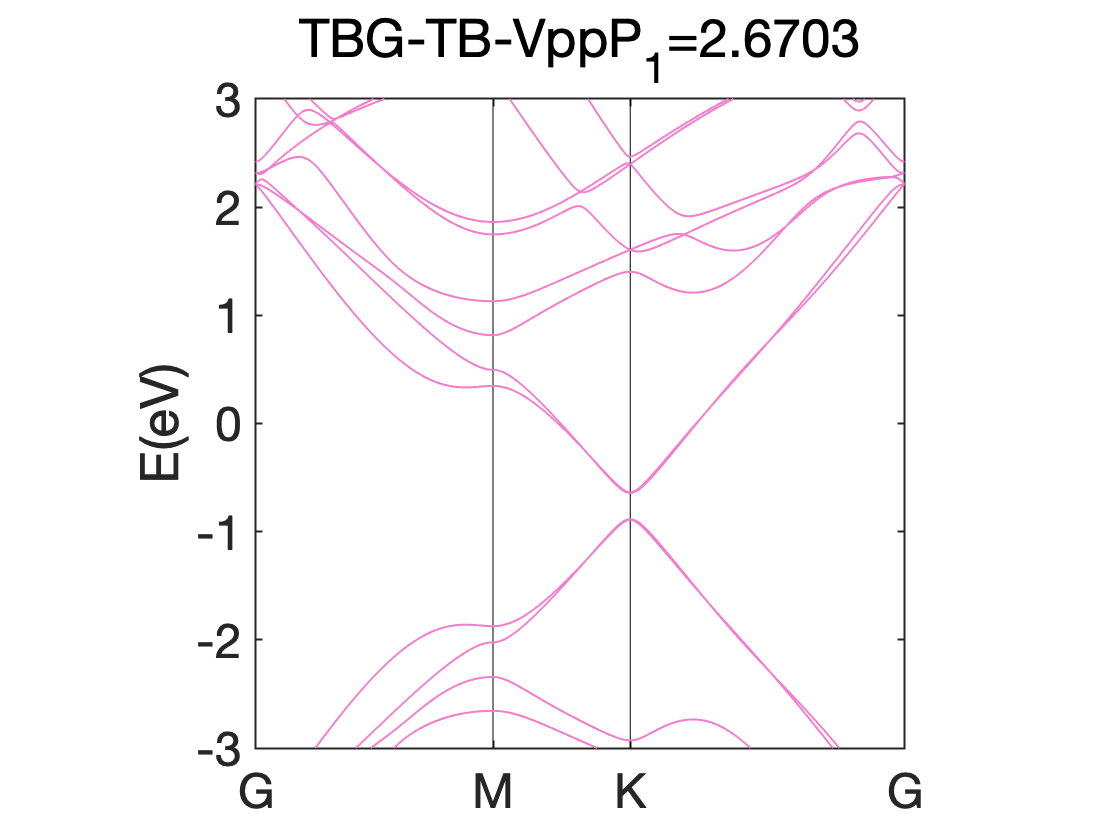

TBG_n = TBG.Subsall();
EIGENCAR = TBG_n.EIGENCAR_gen()-Fermi;
bandplot(EIGENCAR ,[-3,3],"TBG-TB-VppP_1="+string(VppP_1));

## 调整TB轨道

尝试从WAVECAR定义

OUTCAR =TBG_n.EIGENCAR_gen(0,-1,[0 -0 0]);
WAVECAR = OUTCAR.WAVECAR;
BASIS_MAT2 = WAVECAR(:,13:16).';
TBG_p = TBG_n.project(BASIS_MAT2);

- 生成能带

EIGENCAR_p = TBG_p.EIGENCAR_gen();

- 画出能带

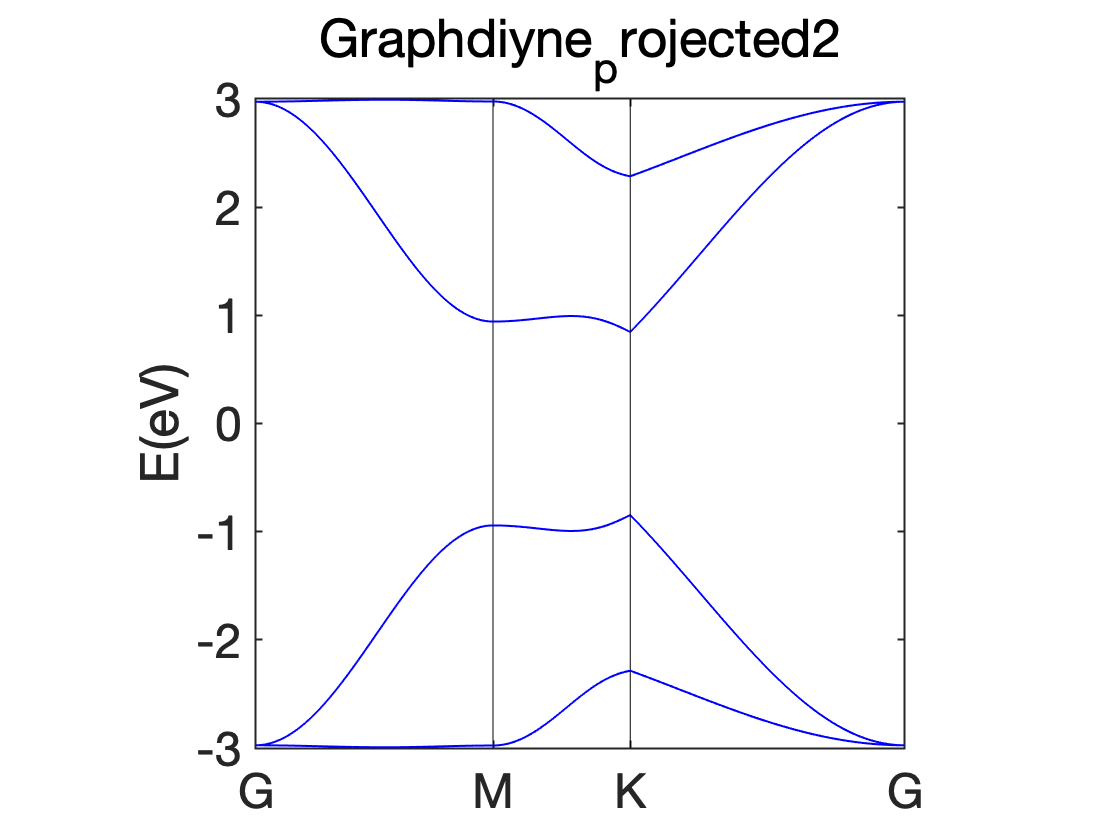

[klist_l,kpoints_l,kpoints_name] = TBG_p.kpath_information();
bandplot(EIGENCAR_p,[-3,3],'Graphdiyne_projected2','b',klist_l,kpoints_l,kpoints_name);

## 输出HR.dat

% TBG_n.Gen_hr('lda_hr.dat');

## 自动给出TBmodel的输入文件

TBG_p.tbbox_in_gen();

Reseq the orbital by your selfWrinting (1/9)  NRPT
Wrinting (2/9)  NRPT
Wrinting (3/9)  NRPT
Wrinting (4/9)  NRPT
Wrinting (5/9)  NRPT
Wrinting (6/9)  NRPT
Wrinting (7/9)  NRPT
Wrinting (8/9)  NRPT
Wrinting (9/9)  NRPT


这个时候如果加上对称性 期待得到 RCN = 1 未测试